clear all
close all

ch_dwnsmpl=5;                                       %give the downsampling rate
ch_rate=2000; ch_rate=ch_rate/ch_dwnsmpl;           %give the silicon probe sampling rate (in Hz)
th.nbins = 40; th.binsize = 360/th.nbins;                                  %give the number of theta bins 
gm.nbins = 20; gm.binsize = 360/gm.nbins;
binscale=(th.binsize/2):(th.binsize):(360-(th.binsize/2));
thbins=(th.binsize/2):th.binsize:(360-(th.binsize/2));
gmbins=(gm.binsize/2):gm.binsize:(360-(gm.binsize/2));
OLM=readtable('OLM_cells.xlsx');

%load('NGF_theta.mat')

## Plotting

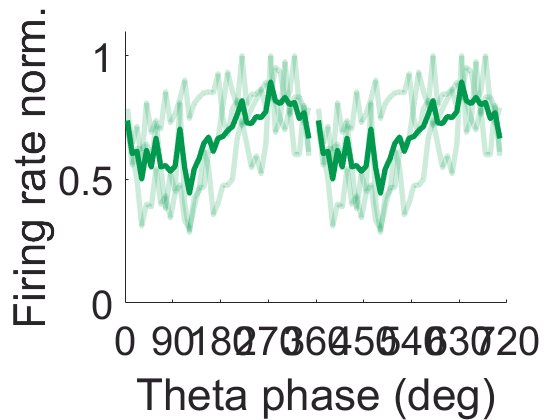

% Theta coupling for all identified OLM cells (coupling normalized)
figure;
for je=1:3
    OLM_theta(je,:) = OLM{je+8, 2:21}./max(OLM{je+8, 2:21});
end
meanTheta=mean(OLM_theta);
line ([gmbins gmbins+360], [meanTheta meanTheta], 'LineWidth', 4, 'Color', [0 0.6 0.3]);
hold on
for je=1:3
    lh=plot([gmbins gmbins+360], repmat(OLM_theta(je,:),1,2), 'linewidth', 4);
    lh.Color=[0 0.6 0.3,0.2];
    hold on
end
lh=plot([gmbins gmbins+360], repmat(OLM{11,2:21},1,2), 'linewidth', 4);

%x=[0:1:720]; y=(cosd(x+180)+1).*0.5; 
% line (x,y, 'Color', 'k', 'LineWidth', 2) % theta
%y=[0:0.1:1];
%axis ([0 720 0 1]);
set (gca, 'Xtick', 0:90:720, ... 
    'FontSize',30)
xlabel ('Theta phase (deg)'); ylabel ('Firing rate norm.')
%pozi=get(gca,'Position'); pozi=[pozi(1) pozi(2) 1.2*pozi(3) 1.2*pozi(4)]; set(gca,'Position',pozi)

xlim([0 720])
ylim([0 1.1])
set(gca, 'Clipping', 'off')  

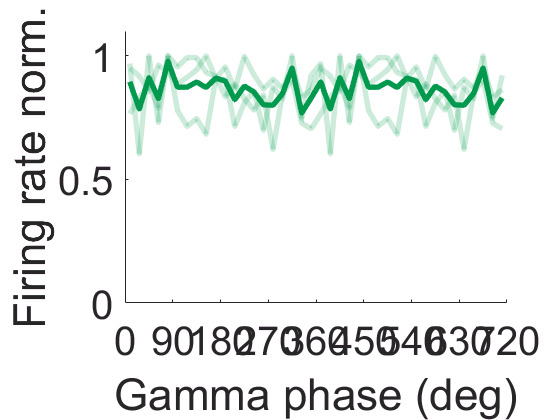

% Mid-gamma coupling for all identified OLM cells (coupling normalized)
figure;
for je=1:3
    OLM_mid(je,:) = OLM{je+4, 43:62}./max(OLM{je+4,43:62});
end
meanMid=mean(OLM_mid);
line ([gmbins gmbins+360], [meanMid meanMid], 'LineWidth', 4, 'Color', [0 0.6 0.3]);
hold on
for je=1:3
    lh=plot([gmbins gmbins+360], repmat(OLM_mid(je,:),1,2), 'linewidth', 4);
    lh.Color=[0 0.6 0.3,0.2];
    hold on
end

%x=[0:1:720]; y=(cosd(x+180)+1).*0.5; 
% line (x,y, 'Color', 'k', 'LineWidth', 2) % theta
%y=[0:0.1:1];
%axis ([0 720 0 1]);
set (gca, 'Xtick', 0:90:720, ... 
    'FontSize',30)
xlabel ('Gamma phase (deg)'); ylabel ('Firing rate norm.')
%pozi=get(gca,'Position'); pozi=[pozi(1) pozi(2) 1.2*pozi(3) 1.2*pozi(4)]; set(gca,'Position',pozi)

xlim([0 720])
ylim([0 1.1])
set(gca, 'Clipping', 'off')

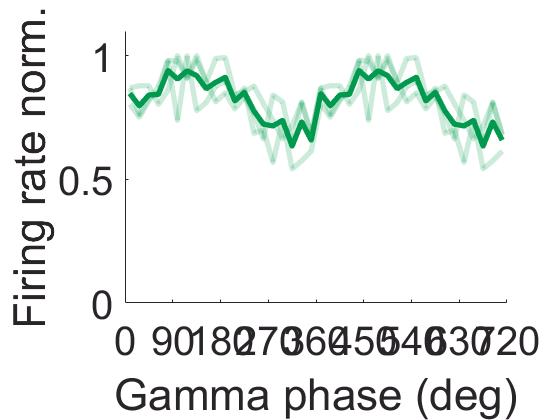

% Fast-gamma coupling for all identified OLM cells (coupling normalized)
figure;
for je=1:3
    OLM_fast(je,:) = OLM{je+4, 64:83}./max(OLM{je+4, 64:83});
end
meanFast=mean(OLM_fast);
line ([gmbins gmbins+360], [meanFast meanFast], 'LineWidth', 4, 'Color', [0 0.6 0.3]);
hold on
for je=1:3
    lh=plot([gmbins gmbins+360], repmat(OLM_fast(je,:),1,2), 'linewidth', 4);
    lh.Color=[0 0.6 0.3,0.2];
    hold on
end

%x=[0:1:720]; y=(cosd(x+180)+1).*0.5; 
% line (x,y, 'Color', 'k', 'LineWidth', 2) % theta
%y=[0:0.1:1];
%axis ([0 720 0 1]);
set (gca, 'Xtick', 0:90:720, ... 
    'FontSize',30)
xlabel ('Gamma phase (deg)'); ylabel ('Firing rate norm.')
%pozi=get(gca,'Position'); pozi=[pozi(1) pozi(2) 1.2*pozi(3) 1.2*pozi(4)]; set(gca,'Position',pozi)

xlim([0 720])
ylim([0 1.1])
set(gca, 'Clipping', 'off')

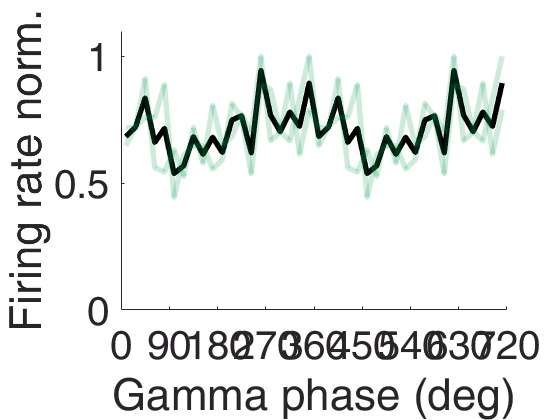

% Slow-gamma coupling for all identified OLM cells (coupling normalized)
figure;
for je=1:3
    OLM_slow(je,:) = OLM{je+4, 85:104}./max(OLM{je+4, 85:104});
end
meanSlow=nanmean(OLM_slow);
line ([gmbins gmbins+360], [meanSlow meanSlow], 'LineWidth', 4, 'Color', 'k');
hold on
for je=1:3
    lh=plot([gmbins gmbins+360], repmat(OLM_slow(je,:),1,2), 'linewidth', 4);
    lh.Color=[0 0.6 0.3,0.2];
    hold on
end

%x=[0:1:720]; y=(cosd(x+180)+1).*0.5; 
% line (x,y, 'Color', 'k', 'LineWidth', 2) % theta
%y=[0:0.1:1];
%axis ([0 720 0 1]);
set (gca, 'Xtick', 0:90:720, ... 
    'FontSize',30)
xlabel ('Gamma phase (deg)'); ylabel ('Firing rate norm.')
%pozi=get(gca,'Position'); pozi=[pozi(1) pozi(2) 1.2*pozi(3) 1.2*pozi(4)]; set(gca,'Position',pozi)

xlim([0 720])
ylim([0 1.1])
set(gca, 'Clipping', 'off')